# ELEC4621 Lab 4

***by Jason Ha (z5115925)***

## Question 1

We are given the following filter with impulse response, $h\left\lbrack n\right\rbrack$ (which is, in fact an ideal low-pass filter):


$$h\left\lbrack n\right\rbrack =\mathrm{sinc}\left(\frac{n}{6}\right)$$


Where $-\infty <n<\infty \;$. Let its alternative notation be $H$, some transformation on an input signal.

### Part (a)

**To test for linearity**

This means an input signal scaled by some factor $A$ will produce an output signal with the same scaling factor. That, we are required to prove that:


$$x_o \left\lbrack n\right\rbrack =A\cdot x\left\lbrack n\right\rbrack \;\;\;\Longrightarrow \;\;y_o \left\lbrack n\right\rbrack =A\cdot y\left\lbrack n\right\rbrack$$


We also know that a filter acts on an input signal by convolution:


$$y\left\lbrack n\right\rbrack =\sum_k x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =\sum_k x\left\lbrack k\right\rbrack \mathrm{sinc}\left(\frac{n-k}{6}\right)\;=H\left(x\left\lbrack n\right\rbrack \right)$$


*Proof:*


$$y_o \left\lbrack n\right\rbrack =H\left(x_o \left\lbrack n\right\rbrack \right)=H\left(A\cdot \;x\left\lbrack n\right\rbrack \right)=\sum_k A\cdot \;x\left\lbrack k\right\rbrack \mathrm{sinc}\left(\frac{n-k}{6}\right)=A\cdot \sum_k x\left\lbrack k\right\rbrack \mathrm{sinc}\left(\frac{n-k}{6}\right)\;=A\cdot H\left(x\left\lbrack n\right\rbrack \right)=A\cdot \;y\left\lbrack n\right\rbrack$$


Hence, the filter is linear.

**To test for time-invariance**

This filter is time-invariant. if a time-shift in the input sequence reflects an identical time-shift in the output sequence. That is:


$$x_o \left\lbrack n\right\rbrack =x\left\lbrack n-n_o \right\rbrack \;\;\;\Longrightarrow \;y_o \left\lbrack n\right\rbrack =y\left\lbrack n-n_0 \right\rbrack$$


*Input Test*


$$y_o \left\lbrack n\right\rbrack =\sum_k x\left\lbrack n-n_0 \right\rbrack \cdot \mathrm{sinc}\left(\frac{n-k}{6}\right)$$


*Output Test*


$$y\left\lbrack n-n_0 \right\rbrack =\sum_k x\left\lbrack n-n_0 \right\rbrack \cdot \mathrm{sinc}\left(\frac{n-n_0 -k}{6}\right)\;$$


Since $y_0 \left\lbrack n\right\rbrack \not= y\left\lbrack n-n_0 \right\rbrack$, we can conclude that $H$ is NOT time-invariant.

**To test for causality**

Our system is causal if, for some impulse $\delta \;\left\lbrack n\right\rbrack$ at $n=0$, the filter produces a response for only $n\ge 0$ and is zero for all $n<0$. Our given impulse response is a sinc function, an even function that is symmetric about the origin. Naturally, the sinc is non-zero for all $n<0$. i.e.


$$h\left\lbrack n\right\rbrack \not= 0\;\;\;\;\;\forall \;n<0$$


Hence, the filter is NOT causal.

### **Part (b)**

The transfer function of the filter can be found by computing the z-transform of the impulse response. That is $h\left\lbrack n\right\rbrack \to^{z-\mathrm{transform}} H\left(z\right)$. That is:


$$H\left(z\right)=\sum_{n=-\infty \;}^{\infty } h\left\lbrack n\right\rbrack z^{-n} =\sum_{n=-\infty \;}^{\infty } \mathrm{sinc}\left(\frac{n}{6}\right)z^{-n}$$


### Part (c)

Suppose $-10<n<10$, enough samples to approximate the true impulse repsonse. We do this in the code cell below:

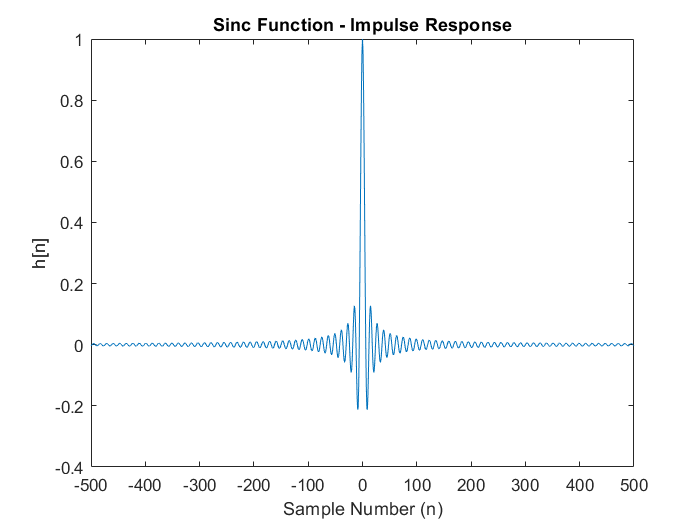

% Initialise an array of sample numbers. Separate samples in increments of
% 1/10
n = -500:1:500;

% Use a for-loop to generate the sinc with an exception at n = 0
y = sinc(n/6);

% Compute the frequency response of the filter. Use FFT. Need to also
% zero-center the frequency axis from -pi to pi
y_hat = fftshift(fft(y,1024));
y_hat_freq = linspace(-pi, pi, length(y_hat));

% Using the FFT, determine the magnitude and phase response of the filter:
mag_sinc = abs(y_hat);
phase_sinc = angle(y_hat);

% Plot the sinc impulse response on a figure and appropriately title:
figure
plot(n,y)
title("Sinc Function - Impulse Response")
ylabel("h[n]")
xlabel("Sample Number (n)")

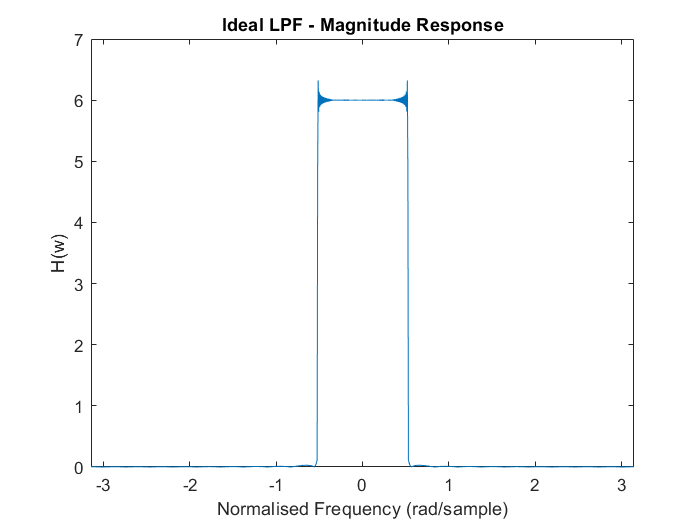


% Plot the magnitude response. X-axis can be the normalised frequency.
figure
plot(y_hat_freq, mag_sinc)
xlim([-pi, pi])
title("Ideal LPF - Magnitude Response")
ylabel("H(w)")
xlabel("Normalised Frequency (rad/sample)")

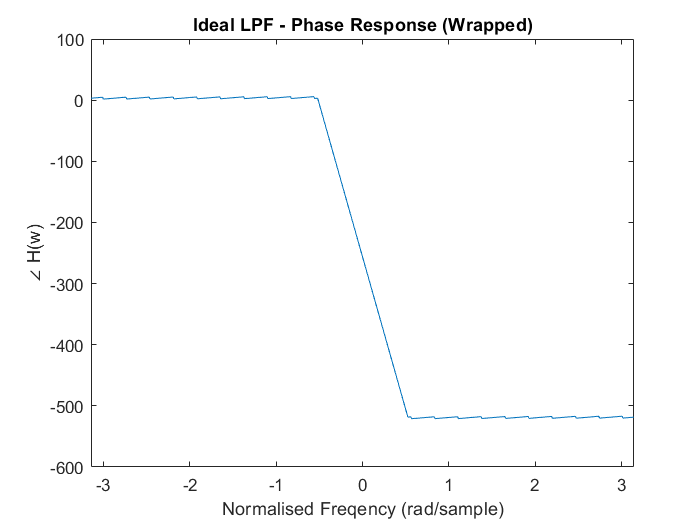


% Plot the phase response. X-axis is still the normalised frequency:
figure
plot(y_hat_freq, unwrap(phase_sinc))
xlim([-pi, pi])
title("Ideal LPF - Phase Response (Wrapped)")
ylabel("\angle H(w)")
xlabel("Normalised Freqency (rad/sample)")

Unsurprisingly, we see an approximation of a rectangular pulse as a result of computing the FFT of the sinc function in the time-domain. It is known of the duality between the two function. That is:


$$\mathrm{sinc}\left(t\right)\leftrightarrow \mathrm{rect}\left(f\right)$$


And vice versa when transforming a rectangular pulse in the time-domain to the sinc function in the frequency domain. The phase response is also linear across all frequencies.

### Part (d)

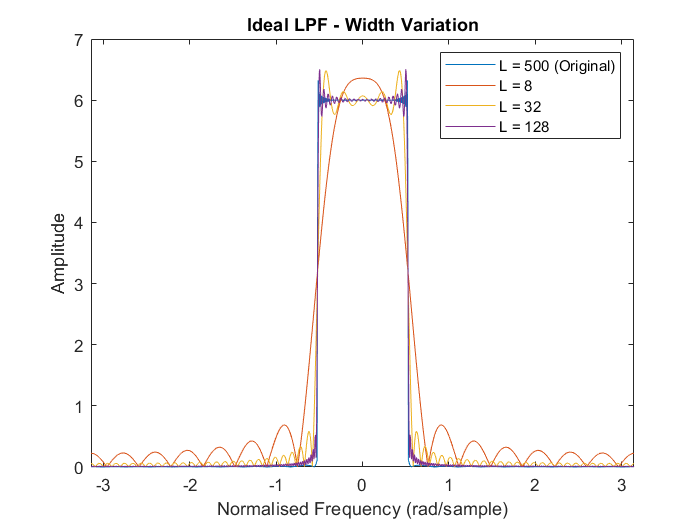

% Create the sample number axes for each variation in the sinc width.
% Increments of 1 (since n must be integer)
n1 = -8:1:8;
n2 = -32:1:32;
n3 = -128:1:128;

% Generate the sincs for each of the above widths:
sinc1 = sinc(n1/6);
sinc2 = sinc(n2/6);
sinc3 = sinc(n3/6);

% Compute the FFT for each sinc and apply the appropriate freq. shifts;
sinc1_hat = fftshift(fft(sinc1, 1024)); sinc1_hat_freq = linspace(-pi, pi, length(sinc1_hat));
sinc2_hat = fftshift(fft(sinc2, 1024)); sinc2_hat_freq = linspace(-pi, pi, length(sinc2_hat));
sinc3_hat = fftshift(fft(sinc3, 1024)); sinc3_hat_freq = linspace(-pi, pi, length(sinc3_hat));

% Compute the magnitude response for each variation:
mag_sinc1 = abs(sinc1_hat);
mag_sinc2 = abs(sinc2_hat);
mag_sinc3 = abs(sinc3_hat);

% Compute the phase response for each variation:
phase_sinc1 = angle(sinc1_hat);
phase_sinc2 = angle(sinc2_hat);
phase_sinc3 = angle(sinc3_hat);

% We can now plot the magnitude response of the variations. Proabably on the same figure to
% emphasize difference:
figure
plot(sinc1_hat_freq, mag_sinc)
hold on
plot(sinc1_hat_freq, mag_sinc1)
hold on
plot(sinc1_hat_freq, mag_sinc2)
hold on
plot(sinc1_hat_freq, mag_sinc3)
title("Ideal LPF - Width Variation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
xlim([-pi,pi])
legend("L = 500 (Original)", "L = 8", "L = 32", "L = 128")

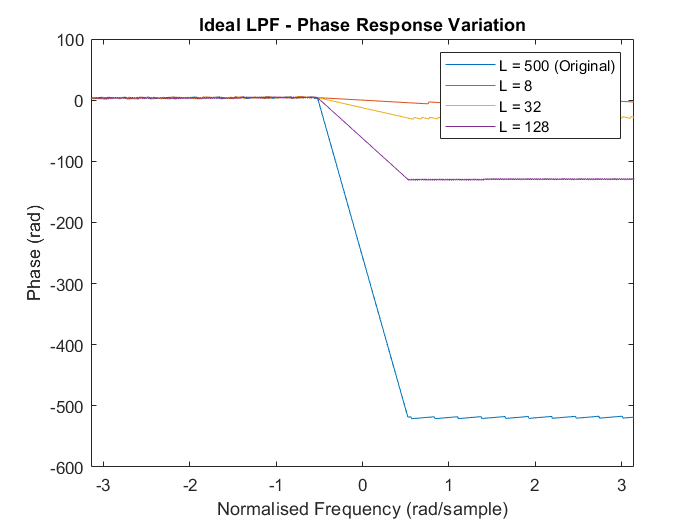


figure
plot(sinc1_hat_freq, unwrap(phase_sinc))
hold on
plot(sinc1_hat_freq, unwrap(phase_sinc1))
hold on
plot(sinc1_hat_freq, unwrap(phase_sinc2))
hold on
plot(sinc1_hat_freq, unwrap(phase_sinc3))
title("Ideal LPF - Phase Response Variation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Phase (rad)")
xlim([-pi, pi])
legend("L = 500 (Original)", "L = 8", "L = 32", "L = 128")

Based on the plots, we can make the following observations:

- As the number of samples of the sinc impulse response increases, the better it is at producing a rectangular pulse in the frequency domain. This is one of the notable properties of the duality between the rectangular pulse and the sinc. The sidelobes of the resulting frequency spectrum also reduce in amplitude after the cutoff frequency as the number of samples increases as well as the ripple in the passband of the filter. We can see that as $L\to \infty$, the frequency response will produce a theoretical ideal (brickwall) LPF.

- As the gradient of the linear phase response of each variation of the sinc function impulse responses progressively increases as the number of samples increases. Since group delay is the derivative of the phase response, an increase in the length of the impulse response will induce a larger constant group delay on the output signal.

- The condition for a digital filter to be realisable is that $2\sigma =N$ or $\sigma =\frac{N}{2}$. That is, the group delay MUST be half of the group delay of the filter. This is due to the restriction that linear phase filters must be symmetric.

### Part (e)

We now want to observe the same characteristics but with a Hanning window applied to the sinc impulse repsonse. Recall that the Hanning window is given by:


$$w\left\lbrack n\right\rbrack =\frac{1}{2}\left\lbrack 1-\mathrm{cos}\left(\frac{2\pi n\;}{N}\right)\right\rbrack$$


When $N$ is the length of the window. The role of the window is to attenuate the sidelobes of the rectnagular pulse produced in the frequency domain.

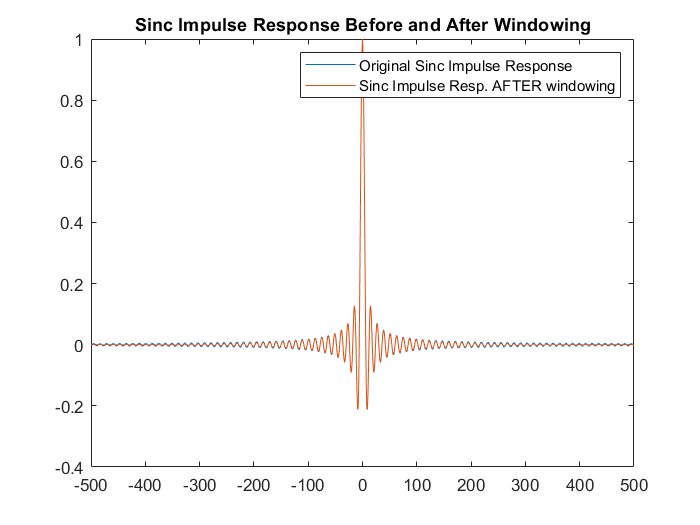

% We need to initialise the hanning window for a defined length N. Let N be the length
% of the impulse response of the sinc. The idea is that we want the hanning
% to make the sinc 'finite' and absolutely integrable.
w = transpose(hamming(length(y)));

% Apply the element-by-element multiplication of the window with the
% signal:
y_w = y .* w;

% Now plot the original signal AND the windowed version on the same figure:
figure
plot(n,y);
hold on
plot(n,y_w);
title("Sinc Impulse Response Before and After Windowing")
xlim([min(n), max(n)])
legend("Original Sinc Impulse Response", "Sinc Impulse Resp. AFTER windowing")

Zooming in to the end points of the windowed sinc, we can see that it attenuates to zero as opposed to the original sinc impulse response that will keep oscillating for all $n\in \left(-\pi \;,\pi \;\right)$. Let's see how this impacts the magnitude and phase spectra.

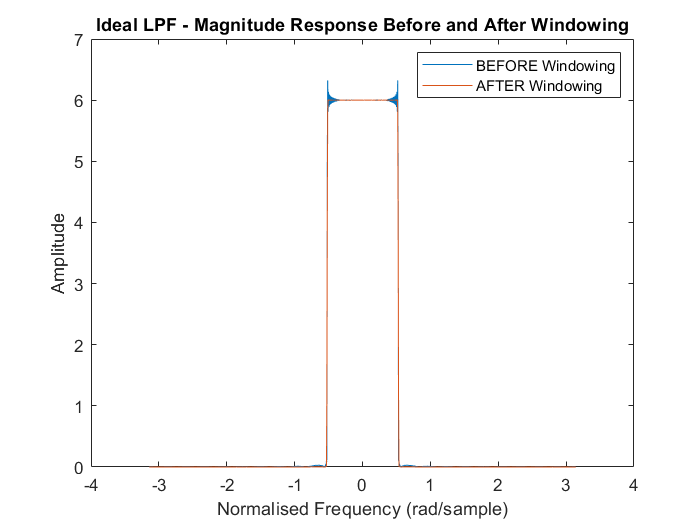

% Compute the FFT of the windowed sinc:
y_w_hat = fftshift(fft(y_w, 1024));
mag_sinc_w = abs(y_w_hat);
phase_sinc_w = angle(y_w_hat);

% Plot the magnitude response of the original sinc and the windowed sinc:
figure
plot(y_hat_freq, mag_sinc);
hold on
plot(y_hat_freq, mag_sinc_w);
title("Ideal LPF - Magnitude Response Before and After Windowing")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
legend("BEFORE Windowing", "AFTER Windowing")

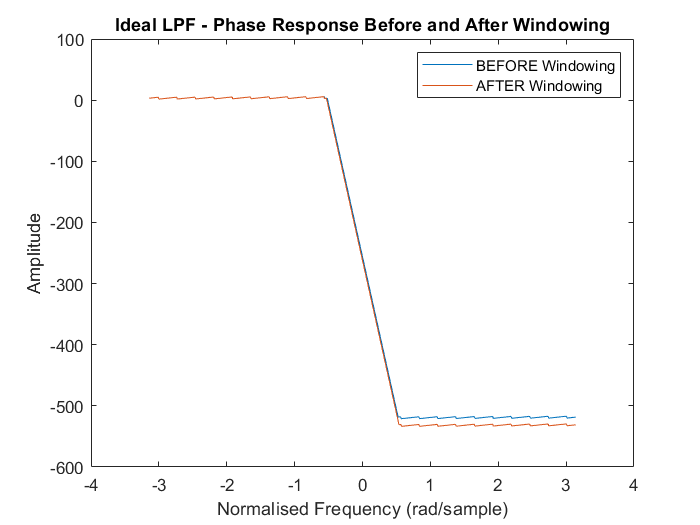


% Plot the phase spectrum of the original and windowed sinc:
figure
plot(y_hat_freq, unwrap(phase_sinc))
hold on
plot(y_hat_freq, unwrap(phase_sinc_w))
title("Ideal LPF - Phase Response Before and After Windowing")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
legend("BEFORE Windowing", "AFTER Windowing")

The importance of the windowing is shown in the magnitude response of the windowed sinc. The most notable effect of the Hanning window is the reduced high order ringing/oscillation right before the cutoff frequencies. Though its not too clear in this example, the side lobes after the cutoff frequencies are relatively reduced as a result of the window.

A better observation of the effect of the Hanning window can be better shown for the shorter length impulse response variations of the sinc.

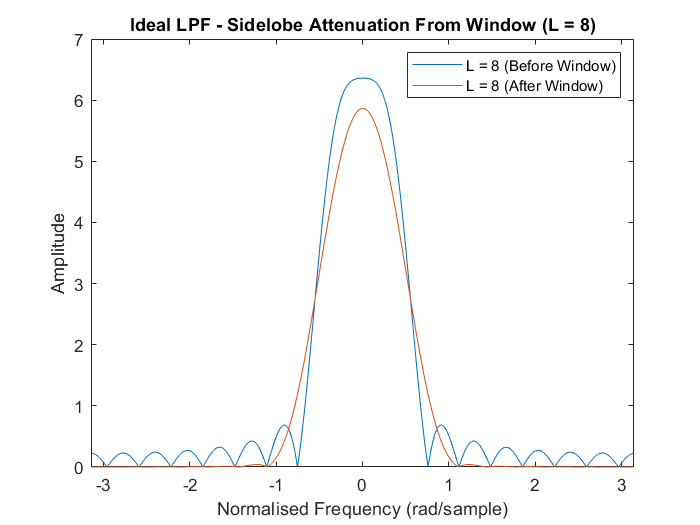

% Create the sample number axes for each variation in the sinc width.
% Increments of 1 (since n must be integer)
n1 = -8:1:8;
n2 = -32:1:32;
n3 = -128:1:128;

% Generate the sincs for each of the above widths:
sinc1w = sinc(n1/6) .* transpose(hanning(length(sinc1)));
sinc2w = sinc(n2/6) .* transpose(hanning(length(sinc2)));
sinc3w = sinc(n3/6) .* transpose(hanning(length(sinc3)));

% Compute the FFT for each sinc and apply the appropriate freq. shifts;
sinc1_hatw = fftshift(fft(sinc1w, 1024)); 
sinc2_hatw = fftshift(fft(sinc2w, 1024)); 
sinc3_hatw = fftshift(fft(sinc3w, 1024));

% Compute the magnitude response for each variation:
mag_sinc1w = abs(sinc1_hatw);
mag_sinc2w = abs(sinc2_hatw);
mag_sinc3w = abs(sinc3_hatw);

% Compute the phase response for each variation:
phase_sinc1w = angle(sinc1_hatw);
phase_sinc2w = angle(sinc2_hatw);
phase_sinc3w = angle(sinc3_hatw);

% We can now plot the magnitude response of the variations. Proabably on the same figure to
% emphasize difference:
figure
plot(sinc1_hat_freq, mag_sinc1)
hold on
plot(sinc1_hat_freq, mag_sinc1w)
title("Ideal LPF - Sidelobe Attenuation From Window (L = 8)")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
xlim([-pi,pi])
legend("L = 8 (Before Window)", "L = 8 (After Window)")

We can already see the Hanning window performing the sidelobe attenuation. Let's see if this is consistent with the rest of the other sinc variations:

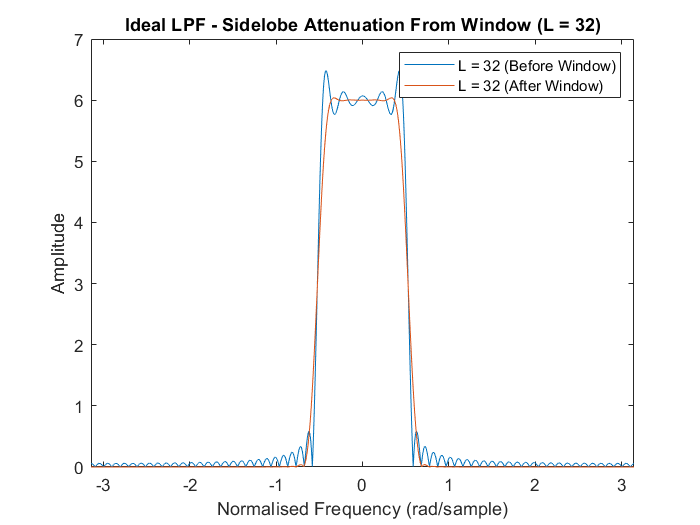

% For L = 32:
figure
plot(sinc2_hat_freq, mag_sinc2)
hold on
plot(sinc2_hat_freq, mag_sinc2w)
title("Ideal LPF - Sidelobe Attenuation From Window (L = 32)")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
xlim([-pi,pi])
legend("L = 32 (Before Window)", "L = 32 (After Window)")

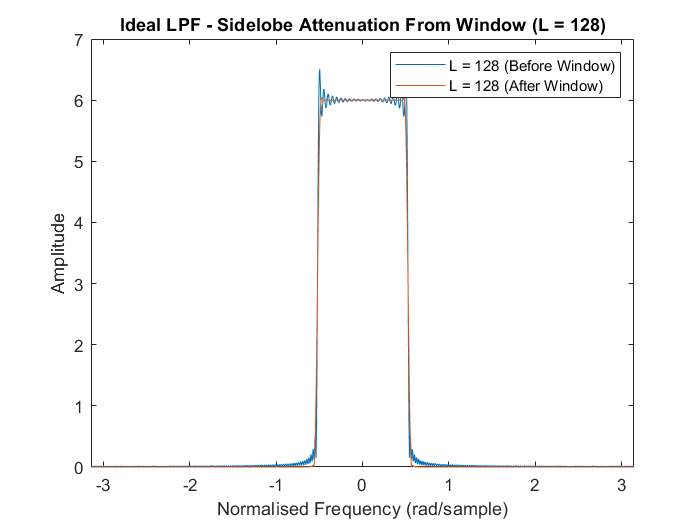


% For L = 128
figure
plot(sinc3_hat_freq, mag_sinc3)
hold on
plot(sinc3_hat_freq, mag_sinc3w)
title("Ideal LPF - Sidelobe Attenuation From Window (L = 128)")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")
xlim([-pi,pi])
legend("L = 128 (Before Window)", "L = 128 (After Window)")

The effect is consistent for all variations in the sinc impulse response. 